# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.9 Spotlight Cross-Range Resolution

## Calculate the cross-range resolution

$\delta_a =\frac{\lambda \;R_{t\;} \;}{2\;L_s }\;\;\left(m\right)$     Equation (2.30)

% Clear the workspace
clear

% Operating frequency (Hz)
operating_frequency = [1e9, 2e9, 6e9, 10e9];

% Slant range (m)
slant_range = 10e3;

% Synthetic aperture length (m)
aperture_length = linspace(10, 200, 1e3);

% Calculate the wavelength (m)
wavelength = 299792458 ./ operating_frequency;

% Calculate the cross-range resolution (m)
for i = 1:length(operating_frequency)
    cross_range_resolution(i,:) = wavelength(i) * slant_range ./ (2 * aperture_length);
end

## Plot the results

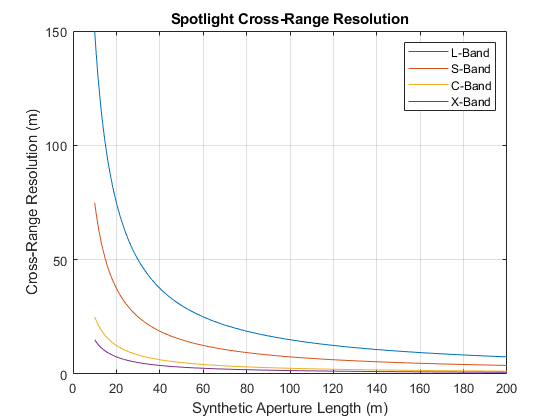

figure;
plot(aperture_length, cross_range_resolution);
xlabel('Synthetic Aperture Length (m)')
ylabel('Cross-Range Resolution (m)');
title('Spotlight Cross-Range Resolution')
grid on
legend('L-Band', 'S-Band', 'C-Band', 'X-Band')